## **UVP5-UVP6 intercalibration**

clear all
close all

disp('Version 2019/06/11')

Version 2019/06/11


## Analyse date

disp(['Processing date : ',datestr(now,31)])

Processing date : 2020-04-01 10:06:22


## Analyse operator

people = input('Enter people first and last name (default : Marc Picheral)','s');
if isempty(people); people = 'Marc Picheral'; end
disp(['Processing operator : ' char(people)]);

Processing operator : Marc Picheral


## Selection of REFERENCE instrument and data

[ref_base, ref_cast] = CalibrationUvpOpenBase('Reference');

>> Select UVP Reference project directory
----------- Base list --------------------------------
1 database in C:\uvp5_sn002_intercalibrage_20200128\results\
N°= 1 : baseuvp5_sn002_intercalibrage_20200128_cal.mat
------------------------------------------------------
Number : 1   >  Profile : int_aa
Number : 2   >  Profile : int_ab
Number : 3   >  Profile : int_ac
Number : 4   >  Profile : int_ad
Number : 5   >  Profile : int_ba
Number : 6   >  Profile : int_bb
Number : 7   >  Profile : int_b_aa
Number : 8   >  Profile : int_b_ba
Number : 9   >  Profile : int_b_ca
Number : 10   >  Profile : int_b_da
Number : 11   >  Profile : int_b_db



if (strcmp(ref_cast.project_folder(4:7),'uvp5'))
    % Reading uvp5_configuration_data.txt REF
    ref_cast.histfile = ref_base.histfile;
    
    filename=[ref_cast.project_folder,'\config\uvp5_settings\uvp5_configuration_data.txt'];
    [ ref_cast.aa_data,ref_cast.expo_data,ref_cast.img_vol_data,ref_cast.pix,ref_cast.light1,ref_cast.light2] = read_uvp5_configuration_data( filename ,'data' );
    % Reading *.hdr REF
    
    filename=[ref_cast.project_folder,'\raw\HDR',char(ref_cast.histfile),'\HDR',char(ref_cast.histfile),'.hdr'];
    [ a,b,c,d,l1,l2,ref_cast.gain,ref_cast.Thres,ref_cast.Exposure,ref_cast.ShutterSpeed,ref_cast.SMBase] = read_uvp5_configuration_data( filename , 'hdr');
    
    % -------------- Checks --------------------------------------------------
    if (ref_base.a0 ~= ref_cast.aa_data || ref_base.exp0 ~= ref_cast.expo_data || ref_base.volimg0 ~= ref_cast.img_vol_data)
        disp('The calibration parameters of the reference UVP are not the same in the data base and in the configuration file. Check them !!! ');
        disp('Configuration_data');
        disp(['Image volume [L]    : ',num2str(ref_cast.img_vol_data)]);
        disp(['Aa                  : ',num2str(ref_cast.aa_data)]);
        disp(['Exp                 : ',num2str(ref_cast.expo_data)]);
        disp('BASE');
        disp(['Image volume [L]    : ',num2str(ref_base.volimg0)]);
        disp(['Aa                  : ',num2str(ref_base.a0)]);
        disp(['Exp                 : ',num2str(ref_base.exp0)]);
        ref_cast.img_vol_data = ref_base.volimg0;
        ref_cast.aa_data = ref_base.a0;
        ref_cast.expo_data = ref_base.exp0;
    else
        disp('All metadata of the reference profile are OK.')
    end
else
    % Reading data from UVP6 base
    ref_cast.aa_data = ref_base.a0/1000000;
    ref_cast.expo_data = ref_base.exp0;
    ref_cast.img_vol_data = ref_base.volimg0;
    ref_cast.pix = ref_base.pixel_size;
    ref_cast.gain = ref_base.gain;
    ref_cast.Thres = ref_base.threshold;
    ref_cast.Exposure = ref_base.shutter;
    ref_cast.ShutterSpeed = ref_base.shutter;
    ref_cast.SMBase    = 1;
    ref_cast.light1 = '';
    ref_cast.light2 = '';
    ref_cast.profilename = ref_base.profilename;
end

All metadata of the reference profile are OK.


ref_cast.label = 'ref';

## Selection of instrument and data to adjust

[adj_base, adj_cast] = CalibrationUvpOpenBase('Adjusted');

>> Select UVP Adjusted project directory
----------- Base list --------------------------------
1 database in C:\uvp6_sn000005lp_2020_intercalibration\results\
N°= 1 : baseuvp6_sn000005lp_2020_intercalibrage.mat
------------------------------------------------------
Number : 1   >  Profile : 20200130-081038_sample_1
Number : 2   >  Profile : 20200130-081038_017_sample_2
Number : 3   >  Profile : 20200130-081038_018_sample_3
Number : 4   >  Profile : 20200130-081038_019_sample_4
Number : 5   >  Profile : 20200130-081038_020_sample_5
Number : 6   >  Profile : 20200130-081038_021_sample_6
Number : 7   >  Profile : 20200130-081038_022_sample_7
Number : 8   >  Profile : 20200130-081038_023_sample_8
Number : 9   >  Profile : 20200130-081038_024_sample_9
Number : 10   >  Profile : 20200130-081038_025_sample_10
Number : 11   >  Profile : 20200130-081038_026_sample_11
Number : 12   >  Profile : 20200130-081038_027_sample_12
Number : 13   >  Profile : 20200130-081038_028_sample_13
Number : 14   


if (strcmp(adj_cast.project_folder(4:7),'uvp5'))
    % Reading uvp5_configuration_data.txt ADJ
    adj_cast.histfile = adj_base.histfile;

    filename=[adj_cast.project_folder,'\config\uvp5_settings\uvp5_configuration_data.txt'];
    [ adj_cast.aa_data, adj_cast.expo_data, adj_cast.img_vol_data, adj_cast.pix, adj_cast.light1 ,adj_cast.light2] = read_uvp5_configuration_data( filename , 'data');
    
    filename=[adj_cast.project_folder,'\raw\HDR',char(adj_base.histfile),'\HDR',char(adj_base.histfile),'.hdr'];
    [ a ,b ,c, d, l1, l2, adj_cast.gain, adj_cast.Thres, adj_cast.Exposure, adj_cast.ShutterSpeed, adj_cast.SMBase] =  read_uvp5_configuration_data( filename , 'hdr');
    % -------------- Checks --------------------------------------------------
    if adj_base.volimg0 ~= adj_cast.img_vol_data
        disp('The image volume of the adjusted UVP is not the same in the data base and in the configuration file. Check the file !!! ');
        disp('Configuration_data');
        disp(['Image volume [L]    : ',num2str(adj_cast.img_vol_data)]);
        disp('BASE');
        disp(['Image volume [L]    : ',num2str(adj_base.volimg0)]);
        adj_cast.img_vol_data = adj_base.volimg0;
    else
        disp('All metadata of the adjusted profile are OK.')
    end
else
    % Reading data from UVP6 base
    adj_cast.aa_data = adj_base.a0;
    adj_cast.expo_data = adj_base.exp0;
    adj_cast.img_vol_data = adj_base.volimg0;
    adj_cast.pix = adj_base.pixel_size;
    adj_cast.gain = adj_base.gain;
    adj_cast.Thres = adj_base.threshold;
    adj_cast.Exposure = adj_base.shutter;
    adj_cast.ShutterSpeed = adj_base.shutter;
    adj_cast.SMBase    = 1;
    adj_cast.light1 = '';
    adj_cast.light2 = '';
    adj_cast.profilename = adj_base.profilename;
end
adj_cast.label = 'adj';

%% Calibration parameters
process_params = CalibrationUvpGetUserProcessParams(adj_cast.uvp, adj_cast.pix);

## Raw data visualization

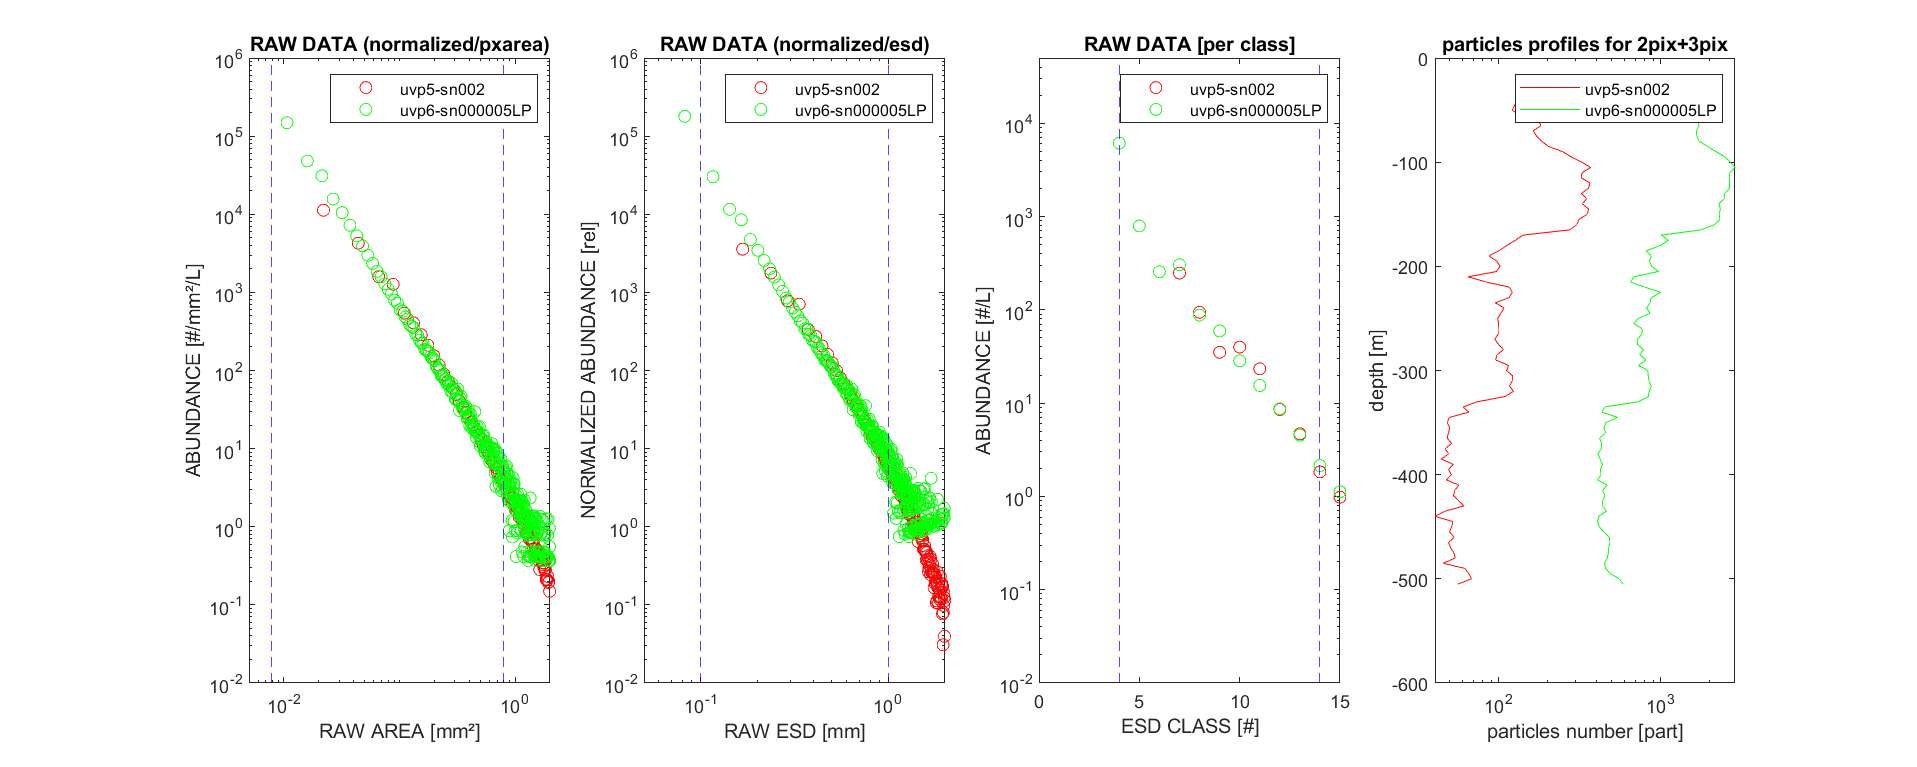

[ref_cast.histopx,adj_cast.histopx, process_params.depth] = CalibrationUvpComputeDepthRange(ref_base.histopx,adj_base.histopx);
[ref_cast] = CalibrationUvpProcessRawData(process_params.esd_vect_ecotaxa, ref_cast);
[adj_cast] = CalibrationUvpProcessRawData(process_params.esd_vect_ecotaxa, adj_cast);
CalibrationUvpPlotRawData(process_params, ref_cast, adj_cast);

ref_cast = CalibrationUvpAdaptToSizeRange(ref_cast, process_params.esd_min, process_params.esd_max);
adj_cast = CalibrationUvpAdaptToSizeRange(adj_cast, process_params.esd_min, process_params.esd_max);

## Fitting on reference data

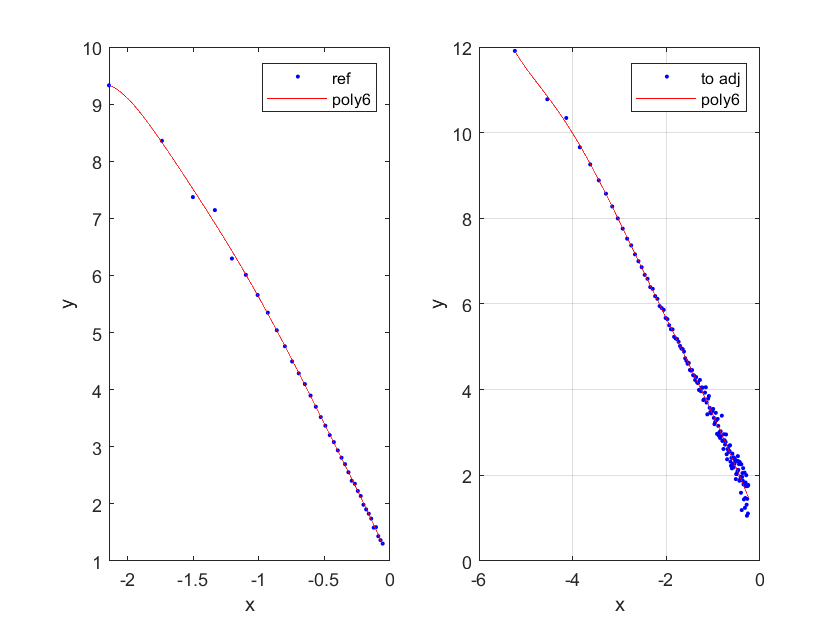

[fitresult] = create_two_fits(ref_cast.esd_calib_log,log(ref_cast.histo_mm2_vol_mean),process_params.fit_type,1,log([1:numel(adj_cast.histo_mm2_vol_mean)].*(adj_cast.pix^2)),log(adj_cast.histo_mm2_vol_mean),process_params.Fit_range);  

[datahistref] = poly_from_fit(ref_cast.esd_calib_log,fitresult,process_params.fit_type);

## Processing calibration

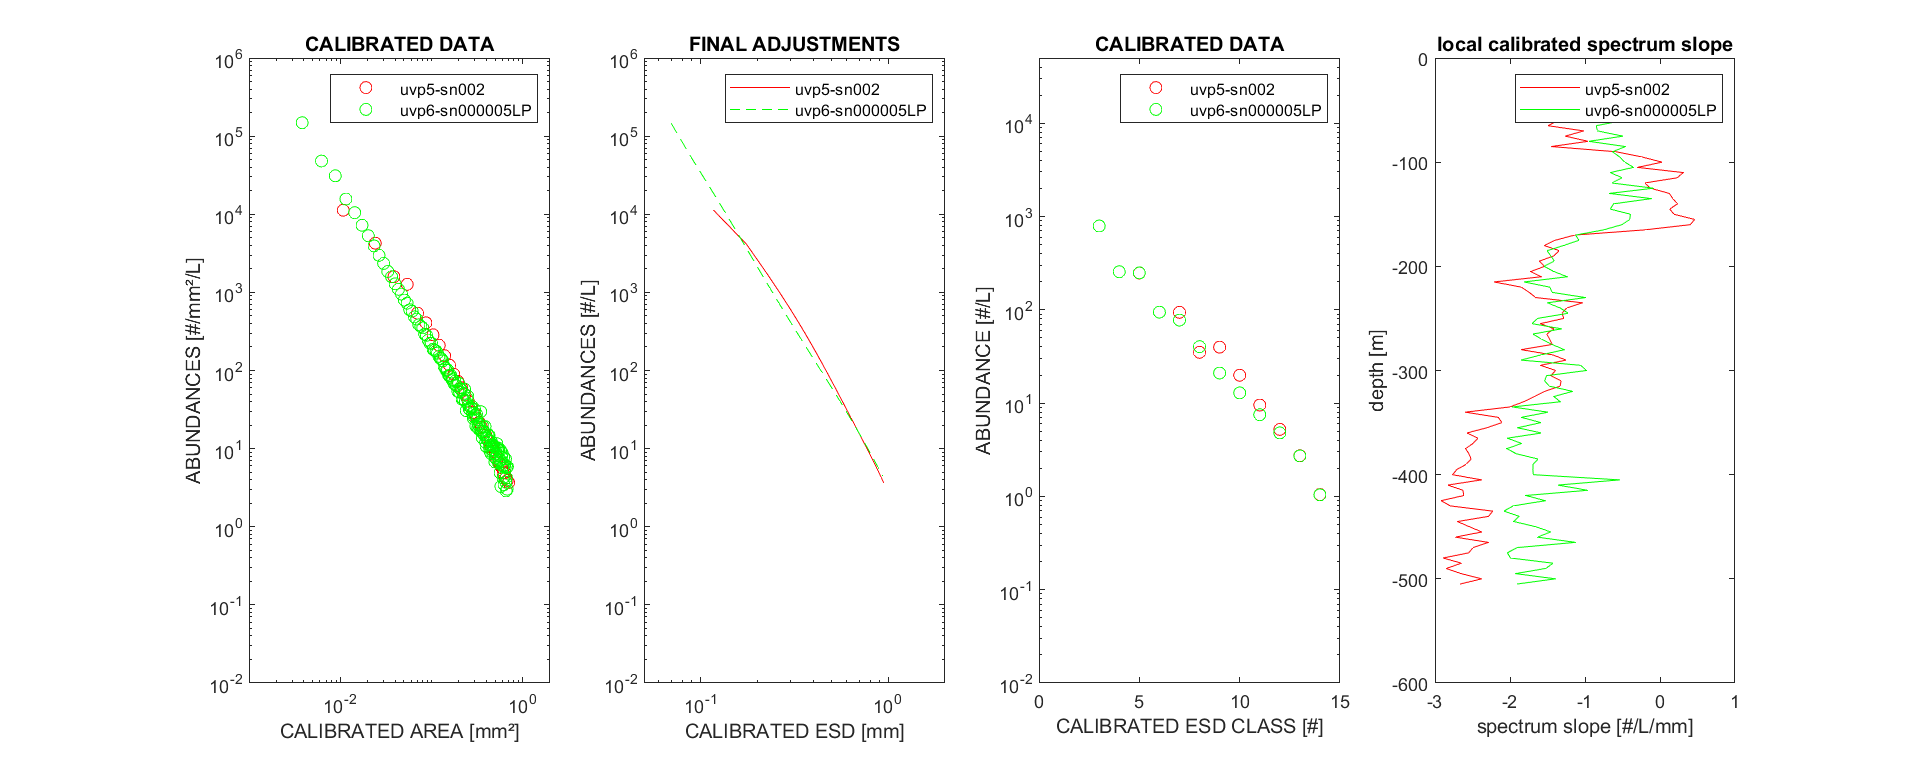

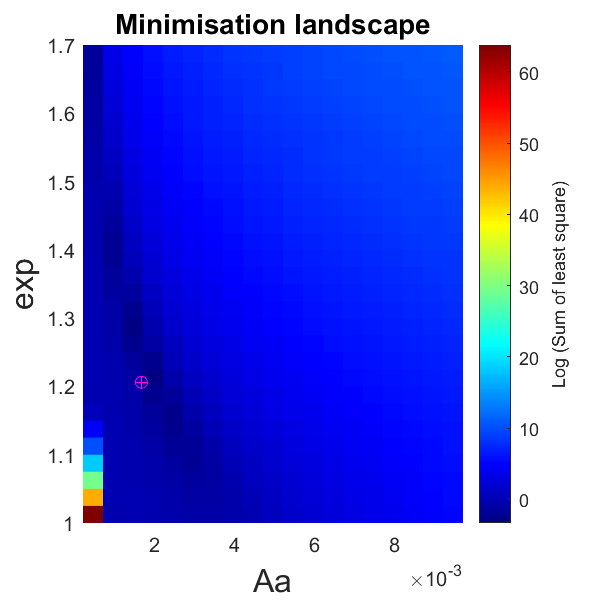

objective_function = @(x)histofunction7_new(x,datahistref, adj_cast.pixsize, adj_cast.histo_mm2_vol_mean, ref_cast.esd_calib_log, process_params.fit_type);
[X,feval]=fminsearch(objective_function,process_params.X0);
aa_adj = X(1);
expo_adj = X(2);
[process_params, ref_cast, adj_cast] = calibration_uvp_settings_b(process_params, ref_cast, adj_cast, datahistref, aa_adj, expo_adj);

disp(' ')

disp(' ')

disp(' ')

disp(' ')

disp(' ')

disp(' ')

disp(' ')

disp(' ')

disp(' ')

disp(' ')

disp(' ')

## Results

CalibrationUvpPrintResults(process_params, ref_cast, adj_cast, aa_adj, expo_adj)

-------------------------------------------------------------------------
Processing date     : 2020-04-01 10:07:20
-------------------------------------------------------------------------
Min ESD       [mm]  : 0.1
Max ESD       [mm]  : 1
Mnimisation start   : [0.0029309 1.1]
Fit                 : poly6
EC factor           : 0.5
EC                  : 0.036282
Ratio (after adjust): 1
-------------------------------------------------------------------------
Reference UVP       : uvp5-sn002
Light 1             :  h002
Light 2             :  h029
Reference folder    : uvp5_sn002_intercalibrage_20200128
Reference profile   : 20200130090714
Reference profile # : 3
Shutter             : 0
Gain                : 6
Threshold           : 21
Exposure            : 9999
SMBase              : 0
Image volume [L]    : 0.96
Pixel        [µm]   : 0.1484
Pixel Area   [µm²]  : 0.022023
Aa                  : 0.0108
Exp                 : 1.165
----------------------------------------------------------------